# **LASSO REGRESSION FOR HOUSE PRICE PREDICTION**

clc, clearvars, close all
data = readtable("melb_data.csv");

Things we have to handle in Preprocessing part:

Fill up missing values in : 

- ** Car **

- ** BuildingArea**

- **YearBuilt**

- **CouncilArea**

# Filling missing car values with most common number of cars

%Filling missing values for the column Car
car_mode = mode(data.Car(~isnan(data.Car))); 
data.Car(isnan(data.Car)) = car_mode;         

# Grouping by `Rooms` when filling BuildingArea because the number of Rooms is a natural predictor of building size, and this keeps the filled values realistic and consistent with similar houses.

%Filling missing values for the column Building Area
uniqueRooms = unique(data.Rooms);
for i = 1:length(uniqueRooms)
    r = uniqueRooms(i);
    rowsInGroup = data.Rooms == r;
    medianBA = median(data.BuildingArea(rowsInGroup & ~isnan(data.BuildingArea)));
    missingBA = isnan(data.BuildingArea) & rowsInGroup;
    data.BuildingArea(missingBA) = medianBA;
end

# Basically houses are built around in the same time in a particular suburb

%Filling missing values for the column Year Built
uniquesuburb = unique(data.Suburb);
for i =1:length(uniquesuburb)
    s = uniquesuburb{i};
    rowsinsuburb = strcmp(data.Suburb, s);
    medianYB = median(data.YearBuilt(rowsinsuburb & ~isnan(data.YearBuilt)));
    missingYB = isnan(data.YearBuilt) & rowsinsuburb;
    data.YearBuilt(missingYB) = medianYB;
end

sum(isnan(data.YearBuilt));
%Here 18 values came so we need to fill the remaining by taking the overall median over the column

globalMedianYB = median(data.YearBuilt, 'omitnan');
data.YearBuilt(isnan(data.YearBuilt)) = globalMedianYB;

# Filling the CoucilArea columns by suburb

%Filling missing values for the column CouncilArea
suburbList = unique(data.Suburb);
for i = 1:length(suburbList)
    s = uniquesuburb{i};
    rowsinsuburb = strcmp(data.Suburb, s);
    knownCouncilAreas = data.CouncilArea(rowsinsuburb & ~ismissing(data.CouncilArea));
    if ~isempty(knownCouncilAreas)
        modeCouncil = mode(categorical(knownCouncilAreas));
        missingIdx = rowsinsuburb & ismissing(data.CouncilArea);
        data.CouncilArea(missingIdx) = cellstr(modeCouncil);
    end
end
sum(ismissing(data.CouncilArea)); %Here 7 were missing so take the global mode
globalMode = mode(categorical(data.CouncilArea(~ismissing(data.CouncilArea))));
data.CouncilArea(ismissing(data.CouncilArea)) = cellstr(globalMode);

data.Address  = []; % Removing the address column
data.Date = []; % Removing the date column
data.SellerG = []; %Removing the sellerG column

## Normalization (Z-score) of numercal columns


$$z=\frac{x-\mu }{\sigma }$$


**It makes feature with zero mean and unit variance, so large scale feature will not dominate**

**Where:**

- $\mu$ = mean of the dataset (average value)

- $\sigma$ = standard deviation of the dataset (measure of spread)

- $x$ = individual data point

- $z$ = normalized value (z-score)

% Split original data before one-hot encoding
numericCols = {'Rooms', 'Price', 'Distance', 'Postcode', 'Bedroom2', ...
               'Bathroom', 'Car', 'Landsize', 'BuildingArea', 'YearBuilt', 'Lattitude', 'Longtitude','Propertycount'};

% Save mean and std of the original (unnormalized) Price
target_mu = mean(data.Price);
target_sigma = std(data.Price);

% Loop through each column and apply z-score normalization
for i = 1:length(numericCols)
    colName = numericCols{i};
    colData = data.(colName);
    mu = mean(colData);
    sigma = std(colData);

    % Avoid division by zero in case of zero std deviation
    if sigma ~= 0
        data.(colName) = (colData - mu) / sigma;
    else
        data.(colName) = zeros(size(colData)); % If std is 0, set to zero vector
    end
end

## ONE-HOT Encode categorical columns

Making categorical text columns to numerical columns

dummyVars = {};
todo = {'Suburb', 'Type', 'Method', 'CouncilArea', 'Regionname'};

for i = 1:length(todo)
    colName = todo{i};
    catVar = categorical(data.(colName));
    encoded = dummyvar(catVar);
    dummyVars{end+1} = encoded;
    data.(colName) = [];
end

oneHotEncodedMatrix = cat(2, dummyVars{:});

numericpart = table2array(data(:,1:end-1));
target = table2array(data(:,end));

data = [numericpart,oneHotEncodedMatrix,target];

writematrix(data, 'preprocessed.csv');

## 1. Data Splitting

This section divides the dataset into training and testing sets.

- **Features Matrix (****A****)**: Contains all predictor variables (columns 1 to end-1).

- **Target Vector (****b****)**: Contains the target variable, which is the house price (the last column).

- **Train-Test Split**: The data is split into a training set (70% of the data) for model training and a testing set (the remaining 30%) for evaluation. This ensures an unbiased assessment of the model's performance on unseen data.

## 2. ADMM Hyperparameters

These are the parameters that control the ADMM algorithm.

- $$ \lambda $
$: A regularization parameter that controls the strength of the penalty on the coefficients. A higher lambda leads to greater sparsity (more coefficients being set to zero).

- $$ \rho $
$: A penalty parameter that affects the convergence rate of the algorithm.

- $$ max_iter $
$: The maximum number of iterations the algorithm will run.

- $$ tol $$ : The convergence tolerance. The algorithm stops when the change in the solution falls below this value.

## 3. The lasso_admm Function

This function is the core of your model, implementing the ADMM algorithm to solve the Lasso problem.

**The Objective Function**

The algorithm seeks to minimize the following objective:


$$$$
\min_{x} \left( \frac{1}{2} ||y - Ax||^2_2 + \lambda ||x||_1 \right)
$$$$


- The first term, $$ ||y - Ax||^2_2 $$, is the equivalent to Mean Squared Error, which measures the model's prediction accuracy.

- The second term, $$ \lambda ||x|_1 $$, is the L1 regularization penalty, which encourages coefficients to be zero.

**ADMM Iterative Updates**

The algorithm works by iteratively updating three variables until convergence.

**Step 1: Update the Coefficients (****x****1)**


$$$$
x_{k+1} = (A^TA + \rho I)^{-1} (A^Tb + \rho(z_k - u_k))
$$$$


**Step 2: Soft Thresholding (****z****1****)**The soft thresholding operator shrinks the coefficients toward zero.


$$$$
z_{k+1} = \mathcal{S}_{\lambda/\rho}(x_{k+1} + u_k)
$$$$


The soft thresholding operator is defined as:


$$$$
\mathcal{S}_{\tau}(x) = \text{sign}(x) \cdot \max(0, |x| - \tau)
$$
$$


- $$ |x| $
$: The absolute value of the coefficient.

- $$ |x| - \tau $$: This shrinks the value. If it's negative, it's set to zero.

- $$ \text{sign}(x) $$: Retains the sign of the original coefficient.

**Step 3: Update the Dual Variable (****u****1****)**


$$$$
u_{k+1} = u_k + (x_{k+1} - z_{k+1})
$$$$


**Step 4: Residual expressions**


$$r^k = x^k - z^k
$$



$$s^k = \rho (z^k - z^{k-1})
$$


## 4. Model Evaluation

After training, the model's performance is evaluated on the test set.

- Root Mean Squared Error (RMSE): Measures the standard deviation of the residuals (prediction errors).


$$$$
\text{RMSE} = \sqrt{\frac{1}{m} \sum_{i=1}^{m} (y_{i, \text{pred}} - y_{i, \text{test}})^2}
$$$$


- Mean Absolute Error (MAE): Measures the average magnitude of the errors.Code snippet


$$$$
\text{MAE} = \frac{1}{m} \sum_{i=1}^{m} |y_{i, \text{pred}} - y_{i, \text{test}}|
$$$$


A = data(:,1:end-1);
b = data(:,end);
g = size(A, 1);
split_index = round(0.7 * g);
A_train = A(1:split_index, :);
A_test  = A(split_index+1:end, :);
b_train = b(1:split_index, :);
b_test  = b(split_index+1:end, :);

lambda = 0.1;
rho = 1.6;
max_iter = 3000;
tol  = 1e-3;

function [x,history] = lasso_admm(A,b,lambda,rho,max_iter,tol)
    [~, n] = size(A);
    z0= zeros(n, 1);
    u0 = zeros(n, 1);
    AtA = A'*A;
    Atb = A'*b;

    history.objval = zeros(max_iter,1);
    history.primal_res = zeros(max_iter,1);
    history.dual_res = zeros(max_iter,1);

    i=1;
    while i<max_iter
        x1 = inv(AtA + rho*eye(n))*(Atb + rho*(z0 - u0));
        z1 = soft_threshold(x1 + u0, lambda / rho);
        u1 = u0 + (x1 - z1);

        r_norm = norm(x1 - z1);
        s_norm = norm(rho*(z1 -z0));

        history.objval(i) = 0.5*norm(A*x1-b)^2 + lambda*norm(z1,1);
        history.primal_res(i) = r_norm;
        history.dual_res(i) = s_norm;

        if (r_norm <= tol && s_norm <=tol)
            fprintf("Converged at %dth iteration\n",i)
            history.objval = history.objval(1:i);
            history.primal_res = history.primal_res(1:i);
            history.dual_res = history.dual_res(1:i);
            break
        end
        z0 = z1;
        u0 = u1;
        i=i+1;
    end
    x= x1;
end

function z = soft_threshold(x, tau)
    z = sign(x) .* max(abs(x) - tau, 0);
end

[x,history] = lasso_admm(A_train,b_train,lambda,rho,max_iter,tol);

Converged at 132th iteration


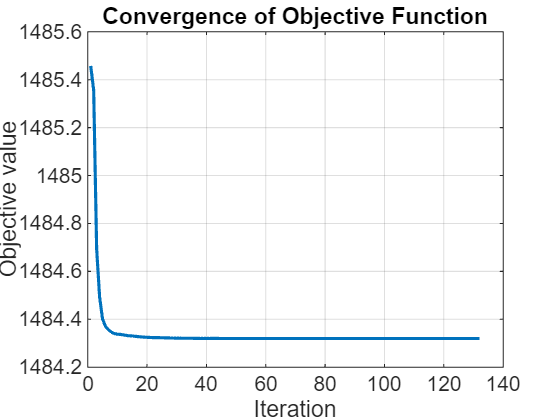

% Plot objective value
figure;
plot(history.objval, 'LineWidth', 1.5);
xlabel('Iteration');
ylabel('Objective value');
title('Convergence of Objective Function');
grid on;

y = A_test * x;
rmse = sqrt(mean((y - b_test).^2));
mae = mean(abs(y - b_test));
disp(['RMSE: ', num2str(rmse)]);

RMSE: 0.72266


disp(['MAE: ', num2str(mae)]);

MAE: 0.39014


[~,n] = size(A);
cvx_clear
cvx_begin quiet
    variables w(n) 
    minimize(0.5*sum_square(A*w-b) + lambda*norm(w,1))
cvx_end
cvx_status

cvx_status = 'Solved'


yaa = A_test*w;
rmse = sqrt(mean((yaa - b_test).^2));
mae = mean(abs(yaa - b_test));
disp(['RMSE: ', num2str(rmse)]);

RMSE: 0.5582


disp(['MAE: ', num2str(mae)]);

MAE: 0.33806
